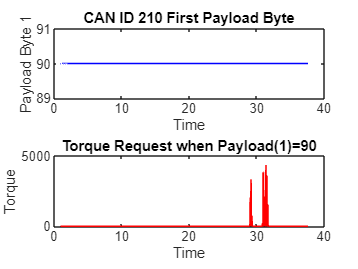

% Read CSV, skipping first 7 rows
data = readmatrix('Standard_Setup_2.csv', 'NumHeaderLines', 7);
time  = data(:,1);   % assuming col1 is timestamp
canID = data(:,3);

% Filter only CAN ID = 210
idx210 = (canID == 210);
time210 = time(idx210,:);
payload = data(idx210, 6:end);  % all payload bytes from col5 onward

% --- Case 1: All CAN ID 210 data in col5 (for general logging) ---
data210 = payload(:,1);  % first payload byte

% --- Case 2: Multiplexed torque message ---
% First byte = 90 means torque message
idxTorque = (payload(:,1) == 90);

timeTorque = time210(idxTorque);

% Combine bytes 2 and 3 of payload (cols 6 and 7 overall in CSV)
lsb = payload(idxTorque,2);  % col6 in original CSV
msb = payload(idxTorque,3);  % col7 in original CSV

% Assemble 16-bit torque
torque16 = bitor(uint16(lsb), bitshift(uint16(msb),8));

% If signed torque (two's complement):
torque16 = typecast(torque16, 'int16');

% --- Plot ---
figure;

subplot(2,1,1);
plot(time210, data210, 'b');
xlabel('Time');
ylabel('Payload Byte 1');
title('CAN ID 210 First Payload Byte');

subplot(2,1,2);
plot(timeTorque, double(torque16), 'r');
xlabel('Time');
ylabel('Torque');
title('Torque Request when Payload(1)=90');


% Keep only non-zero torque values
nonZeroTorque = double(torque16(torque16 ~= 0));

% Compute statistics
avgTorque = mean(nonZeroTorque);
maxTorque = max(nonZeroTorque);

fprintf('Average torque = %.2f\n', avgTorque);

Average torque = 1427.96


fprintf('Max torque     = %.2f\n', maxTorque);

Max torque     = 4353.00



% Keep only non-zero torque values + their timestamps
nonZeroIdx = (torque16 ~= 0);
nonZeroTorque = double(torque16(nonZeroIdx));
nonZeroTime   = timeTorque(nonZeroIdx);

% Compute statistics
[ maxTorque, maxIdx ] = max(nonZeroTorque);
avgTorque = mean(nonZeroTorque);
timeAtMax = nonZeroTime(maxIdx);

fprintf('Average torque = %.2f\n', avgTorque);

Average torque = 1427.96


fprintf('Max torque     = %.2f at time %.6f\n', maxTorque, timeAtMax);

Max torque     = 4353.00 at time 31.376980
